Lab5 第一題

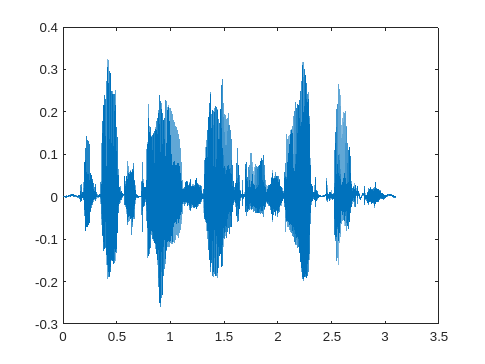

fileName = 'welcome.wav';
[y, fs] = audioread(fileName);
sound(y, fs);
time = (1:length(y))/fs;
plot(time, y);

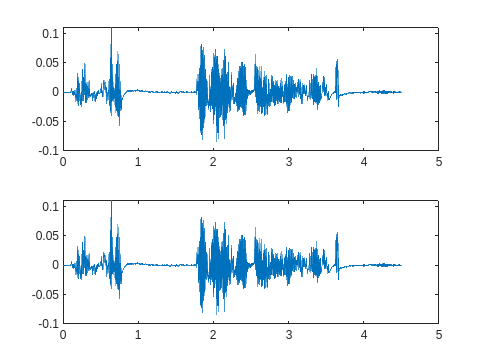

pause(time + 2);
fileName = 'flanger.wav';
[y, fs] = audioread(fileName);
sound(y, fs);
left = y(:,1);
right = y(:,2);
figure;
subplot(211);
plot((1:length(left))/fs, left);
subplot(212);
plot((1:length(right))/fs, right);

figure;

Lab5 第二題

fileName = 'welcome.wav';
[y, fs] = audioread(fileName);
pause(time + 3);
p = audioplayer(1*y, fs);   playblocking(p);
p = audioplayer(3*y, fs);   playblocking(p);
p = audioplayer(5*y, fs);   playblocking(p);
%乘的數字越大，聲音越大聲
p = audioplayer(y, 1.0*fs);   playblocking(p);
p = audioplayer(y, 1.2*fs);   playblocking(p);
p = audioplayer(y, 1.5*fs);   playblocking(p);
p = audioplayer(y, 2.0*fs);   playblocking(p);
%乘的數字越大，聲音的速度越快，音調也越高
p = audioplayer(y, fs); playblocking(p);
p = audioplayer(-y, fs); playblocking(p);
%基本上聽不出差異

Lab5 第三題 

fs = 11025;     nBits = 8;
nChannel = 1;   duration = 4;
waveFile = '61375017H_陳昕佑.wav';
recObj = audiorecorder(fs, nBits, nChannel);
fprintf('Press any key to start recording for %g seconds:', duration);pause

Press any key to start recording for 4 seconds:

recordblocking(recObj, duration);
fprintf('End of recording\n');

End of recording


fprintf('Press any key to start saving audio to %s file...', waveFile); pause

Press any key to start saving audio to 61375017H_陳昕佑.wav file...

y = getaudiodata(recObj, 'double');
audiowrite(waveFile, y, fs);
fprintf('File saving completed\n');

File saving completed


fprintf('Press any key to start playback %s...\n', waveFile);pause

Press any key to start playback 61375017H_陳昕佑.wav...


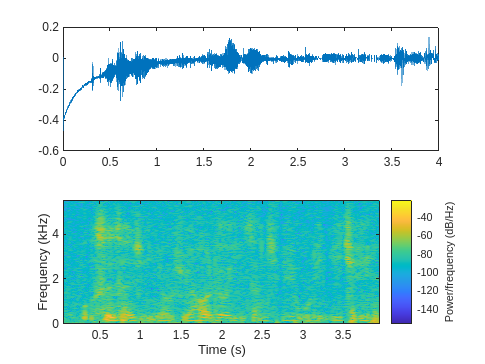

p = audioplayer(y, fs);     playblocking(p);
figure;
time = (1:length(y))/fs;
subplot(211);
plot(time, y);
subplot(212);
spectrogram(y, 1024, 1000, [], fs, 'yaxis');

Lab5 第四題

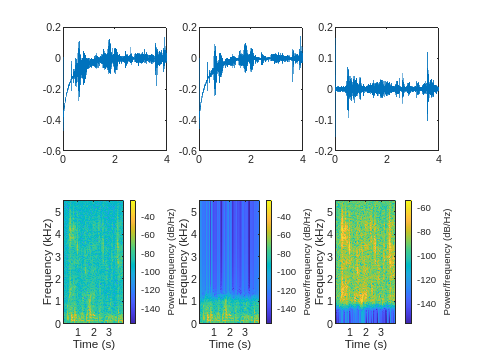

[x, fs] = audioread('61375017H_陳昕佑.wav');
x = x(:, 1);
[b, a] = butter(12, 1000/(fs/2), 'low');
y1 = filter(b, a, x);
time = (1:length(y1))/fs;
figure;
subplot(231);
plot(time, x);
subplot(234);
spectrogram(x, 1024, 1000, [], fs, 'yaxis');
subplot(232);
plot(time, y1);
subplot(235);
spectrogram(y1, 1024, 1000, [], fs, 'yaxis');
[b, a] = butter(12, 1000/(fs/2), 'high');
y2 = filter(b, a, x);
subplot(233);
plot(time, y2);
subplot(236);
spectrogram(y2, 1024, 1000, [], fs, 'yaxis');

%The audio's spectrograsm which prosessed by low pass filter only has
%signal in low frequency. High pass filter allows the signal in higher
%frequency.

Lab5 第五題

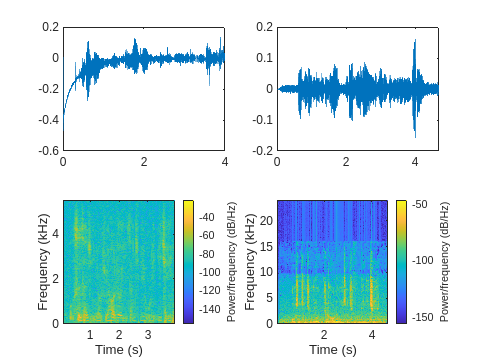

[x1, fs1] = audioread('61375017H_陳昕佑.wav');
[x2, fs2] = audioread('Phone_Recording.wav');
p1 = audioplayer(x1, fs1);     playblocking(p1);  pause(time);
p2 = audioplayer(x2, fs2);     playblocking(p2);  pause(time);
figure;
time1 = (1:length(x1))/fs1;
time2 = (1:length(x2))/fs2;
subplot(221);
plot(time1, x1);
subplot(222);
plot(time2, x2);
subplot(223);
spectrogram(x1, 1024, 1000, [], fs1, 'yaxis');
subplot(224);
spectrogram(x2, 1024, 1000, [], fs2, 'yaxis');

%The audio recording by mobile phone is more clear and louder.

Lab5 第六題

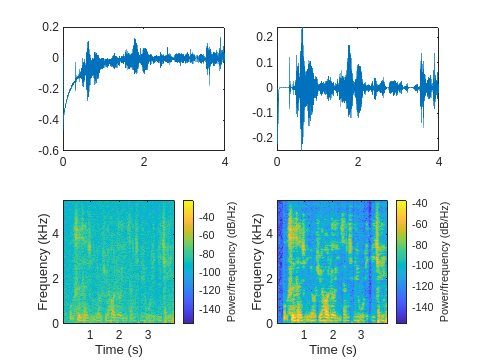

[x, fs] = audioread('61375017H_陳昕佑.wav');
time = (1:length(x))/fs;
output1 = WienerScalart96(x, fs);
t_filtered = (1:length(output1)) / fs;
p = audioplayer(x, fs);     playblocking(p);  pause(time);
p = audioplayer(output1, fs);     playblocking(p);  pause(t_filtered);
figure;
subplot(221);
plot(time, x);
subplot(222);
plot(t_filtered, output1);
subplot(223);
spectrogram(x, 1024, 1000, [], fs, 'yaxis');
subplot(224);
spectrogram(output1, 1024, 1000, [], fs, 'yaxis')